# `DEMO_04:`   4-bar linkage analysis** - Jacobians**

Let's explore some the Jacobians of the 4bar linkage shown in Figure_01 below.  

`Bradley Horton : 24-Jul-2019, bhorton@mathworks.com`

**Figure 01:  the 4bar linkage**

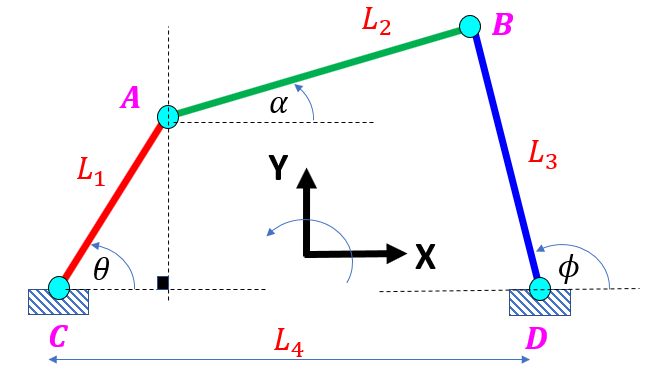

From our earlier Kinematic analysis we derived the relationships:

- $\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)\;\;=L_4 \;-\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)\;+\;\;\;L_3 \ldotp \mathrm{cos}\left(\phi \right)$  ` .....    EQ_1`

- $L_1 \ldotp \mathrm{cos}\left(\theta \right)\;\;=L_4 \;-\;\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)\;+\;\;\;L_3 \ldotp \mathrm{cos}\left(\phi \right)$     `.....    EQ_1b`

And

- $L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\phi \right)\;\;-\;\;L_1 \ldotp \mathrm{sin}\left(\theta \right)\;$    `.....    EQ_2`

- $L_1 \ldotp \mathrm{sin}\left(\theta \right)\;\;=\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\phi \right)\;\;-\;L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;$     `.....    EQ_2b`

Now take the time derivative of `EQ_1b` and `EQ_2b` and we get :

- ${-L}_1 \ldotp \mathrm{sin}\left(\theta \right)\ldotp \theta^˙ \;\;\;\;=\;\;L_2 \ldotp \mathrm{sin}\left(\alpha \right)\ldotp \alpha^˙ \;\;\;-\;L_3 \ldotp \mathrm{sin}\left(\phi \right)\ldotp \phi^˙$      `.....    EQ_1c`

-    $L_1 \ldotp \mathrm{cos}\left(\theta \right)\ldotp \theta^˙ \;\;\;=\;\;\;\;L_3 \ldotp \mathrm{cos}\left(\phi \right)\ldotp \phi^˙ \;\;-L_2 \ldotp \mathrm{cos}\left(\alpha \right)\ldotp \alpha^˙ \;$     `.....    EQ_2c`

If we rewrite these last 2 equations in matrix form, we get:

- $\left\lbrack \begin{array}{c}
{-L}_1 \ldotp \mathrm{sin}\left(\theta \right)\\
\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)
\end{array}\right\rbrack \ldotp \theta^˙ \;\;=\;\;\left\lbrack \begin{array}{cc}
-\;L_3 \ldotp \mathrm{sin}\left(\phi \right) & L_2 \ldotp \mathrm{sin}\left(\alpha \right)\\
L_3 \ldotp \mathrm{cos}\left(\phi \right) & -L_2 \ldotp \mathrm{cos}\left(\alpha \right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\phi^˙ \\
\;\dot{\alpha \;} 
\end{array}\right\rbrack$    `.....    EQ_2d`

Which has the general shape:

- $\left\lbrack \begin{array}{c}
f\left(\theta \right)
\end{array}\right\rbrack \ldotp \theta^˙ \;=\;\left\lbrack \begin{array}{c}
A\left(\phi ,\alpha \right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\phi^˙ \\
\alpha^˙ 
\end{array}\right\rbrack$  which can then be rearranged to:

- 
$$\left\lbrack \begin{array}{c}
\phi^˙ \\
\;\alpha^˙ \;
\end{array}\right\rbrack =\;\;{\left\lbrack \begin{array}{c}
A\left(\phi ,\alpha \right)
\end{array}\right\rbrack }^{-1} \;\ldotp \;\left\lbrack \begin{array}{c}
f\left(\theta \right)
\end{array}\right\rbrack \;\ldotp \theta^˙ \;$$


So doing the rearrangement and the matrix inverse, leads to:

- $\left\lbrack \begin{array}{c}
\phi^˙ \\
\alpha^˙ 
\end{array}\right\rbrack \;\;=\;\;\;\frac{1}{L_3 \ldotp L_2 \ldotp \mathrm{sin}\left(\phi \right)\ldotp \mathrm{cos}\left(\alpha \right)-L_3 \ldotp L_2 \ldotp \mathrm{cos}\left(\phi \right)\ldotp \mathrm{sin}\left(\alpha \right)}\ldotp \left\lbrack \begin{array}{cc}
-L_2 \ldotp \mathrm{cos}\left(\alpha \right) & -L_2 \ldotp \mathrm{sin}\left(\alpha \right)\\
-L_3 \ldotp \mathrm{cos}\left(\phi \right) & -\;L_3 \ldotp \mathrm{sin}\left(\phi \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{-L}_1 \ldotp \mathrm{sin}\left(\theta \right)\\
\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)
\end{array}\right\rbrack \ldotp \theta^˙ \;\;\;\;$   `..... EQ_3`

 **ATTENTION**:  ***IFFFF the machine can be placed into a configuration where the determinant of ***$\;\left\lbrack \begin{array}{c}
A\left(\phi ,\alpha \right)
\end{array}\right\rbrack$*** is zero, then our mathematical description fails - it is a "gymbol lock" situation of sorts.***

The big result summarised in `EQ_3` are the Jacobians.  Recall that our kinematic analysis allowed us to write:

- 
$$\phi =f\left(\theta \right)$$


- 
$$\alpha =g\left(\theta \right)$$


Therefore:

- 
$$\phi^˙ \;=\;\frac{d\phi }{\mathrm{dt}}\;=\;\frac{\partial \phi }{\partial \theta }\ldotp \frac{d\theta }{\mathrm{dt}}\;\;=\;\;\frac{\partial \phi }{\partial \theta }\ldotp \theta^˙$$


- 
$$\alpha^˙ \;=\;\frac{d\alpha }{\mathrm{dt}}\;=\;\frac{\partial \alpha }{\partial \theta }\ldotp \frac{d\theta }{\mathrm{dt}}\;\;\;\;=\;\;\frac{\partial \alpha }{\partial \theta }\ldotp \theta^˙$$


So `EQ_3` can also be written as:

- 
$$\left\lbrack \begin{array}{c}
\phi^˙ \\
\alpha^˙ 
\end{array}\right\rbrack \;\;=\;\;\;\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \ldotp \theta^˙ \;\;$$


where the Jacobians can be written as:

- 
$$\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \;\;=\;\;\;\frac{1}{L_3 \ldotp L_2 \ldotp \mathrm{sin}\left(\phi \right)\ldotp \mathrm{cos}\left(\alpha \right)-L_3 \ldotp L_2 \ldotp \mathrm{cos}\left(\phi \right)\ldotp \mathrm{sin}\left(\alpha \right)}\ldotp \left\lbrack \begin{array}{cc}
-L_2 \ldotp \mathrm{cos}\left(\alpha \right) & -L_2 \ldotp \mathrm{sin}\left(\alpha \right)\\
-L_3 \ldotp \mathrm{cos}\left(\phi \right) & -\;L_3 \ldotp \mathrm{sin}\left(\phi \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{-L}_1 \ldotp \mathrm{sin}\left(\theta \right)\\
\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)
\end{array}\right\rbrack$$


Let's revisit the ***determinant of ***$\;\left\lbrack \begin{array}{c}
A\left(\phi ,\alpha \right)
\end{array}\right\rbrack$:

- 
$$\;\mathrm{det}\left(A\right)=L_3 \ldotp L_2 \ldotp \left(\;\;\mathrm{sin}\left(\phi \right)\ldotp \mathrm{cos}\left(\alpha \right)-\mathrm{cos}\left(\phi \right)\ldotp \mathrm{sin}\left(\alpha \right)\;\;\right)\;$$


So let's visualize this as a surface:

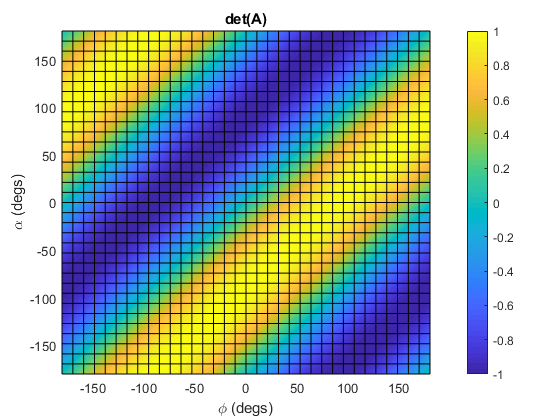

F = @(phi, alpha) sind(phi).*cosd(alpha) - cosd(phi).*sind(alpha);

figure;
 fsurf(F, [-180 180  -180 180])
     xlabel("\phi (degs)"); ylabel("\alpha (degs)")
     view([-0.46 90.00])
     title("det(A)")
     colorbar

And let's draw the contours where $\mathrm{det}\left(A\right)=0\;$:

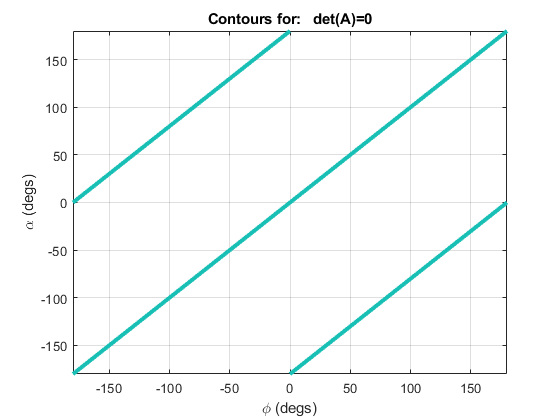

figure;
 fcontour(F, [-180 180  -180 180], "LevelList",[0],"LineWidth",3)
     xlabel("\phi (degs)"); ylabel("\alpha (degs)")
     grid("on")
     title("Contours for:   det(A)=0")  

# We've put these contours into the 4bar APP:

When you use the 4bar mechanism app:

- `>> bh_4bar_explore_app`

You'll see that we've inserted these contours:

- 
$$0\;=\;\mathrm{det}\left(A\right)=L_3 \ldotp L_2 \ldotp \left(\;\;\mathrm{sin}\left(\phi \right)\ldotp \mathrm{cos}\left(\alpha \right)-\mathrm{cos}\left(\phi \right)\ldotp \mathrm{sin}\left(\alpha \right)\;\;\right)$$


 into the "`Angles_flat---DET_Jacobs`" plots, eg: